# Chemical Process Optimization Overview

The process considered here is a Continuous Stirred Tank Reactor (CSTR) during transition from low to high conversion rate (high to low residual concentration). Because the chemical reaction is exothermic (produces heat), the reactor temperature must be controlled to prevent a thermal runaway. The control task is complicated by the fact that the process dynamics are nonlinear and transition from stable to unstable and back to stable as the conversion rate increases. The reactor dynamics are modeled in Simulink. The controlled variables (states) are the residual concentration $C_r$ and the reactor temperature $T_r$, and the manipulated variable (action) is the temperature $T_c$ of the coolant circulating in the reactor's cooling jacket.

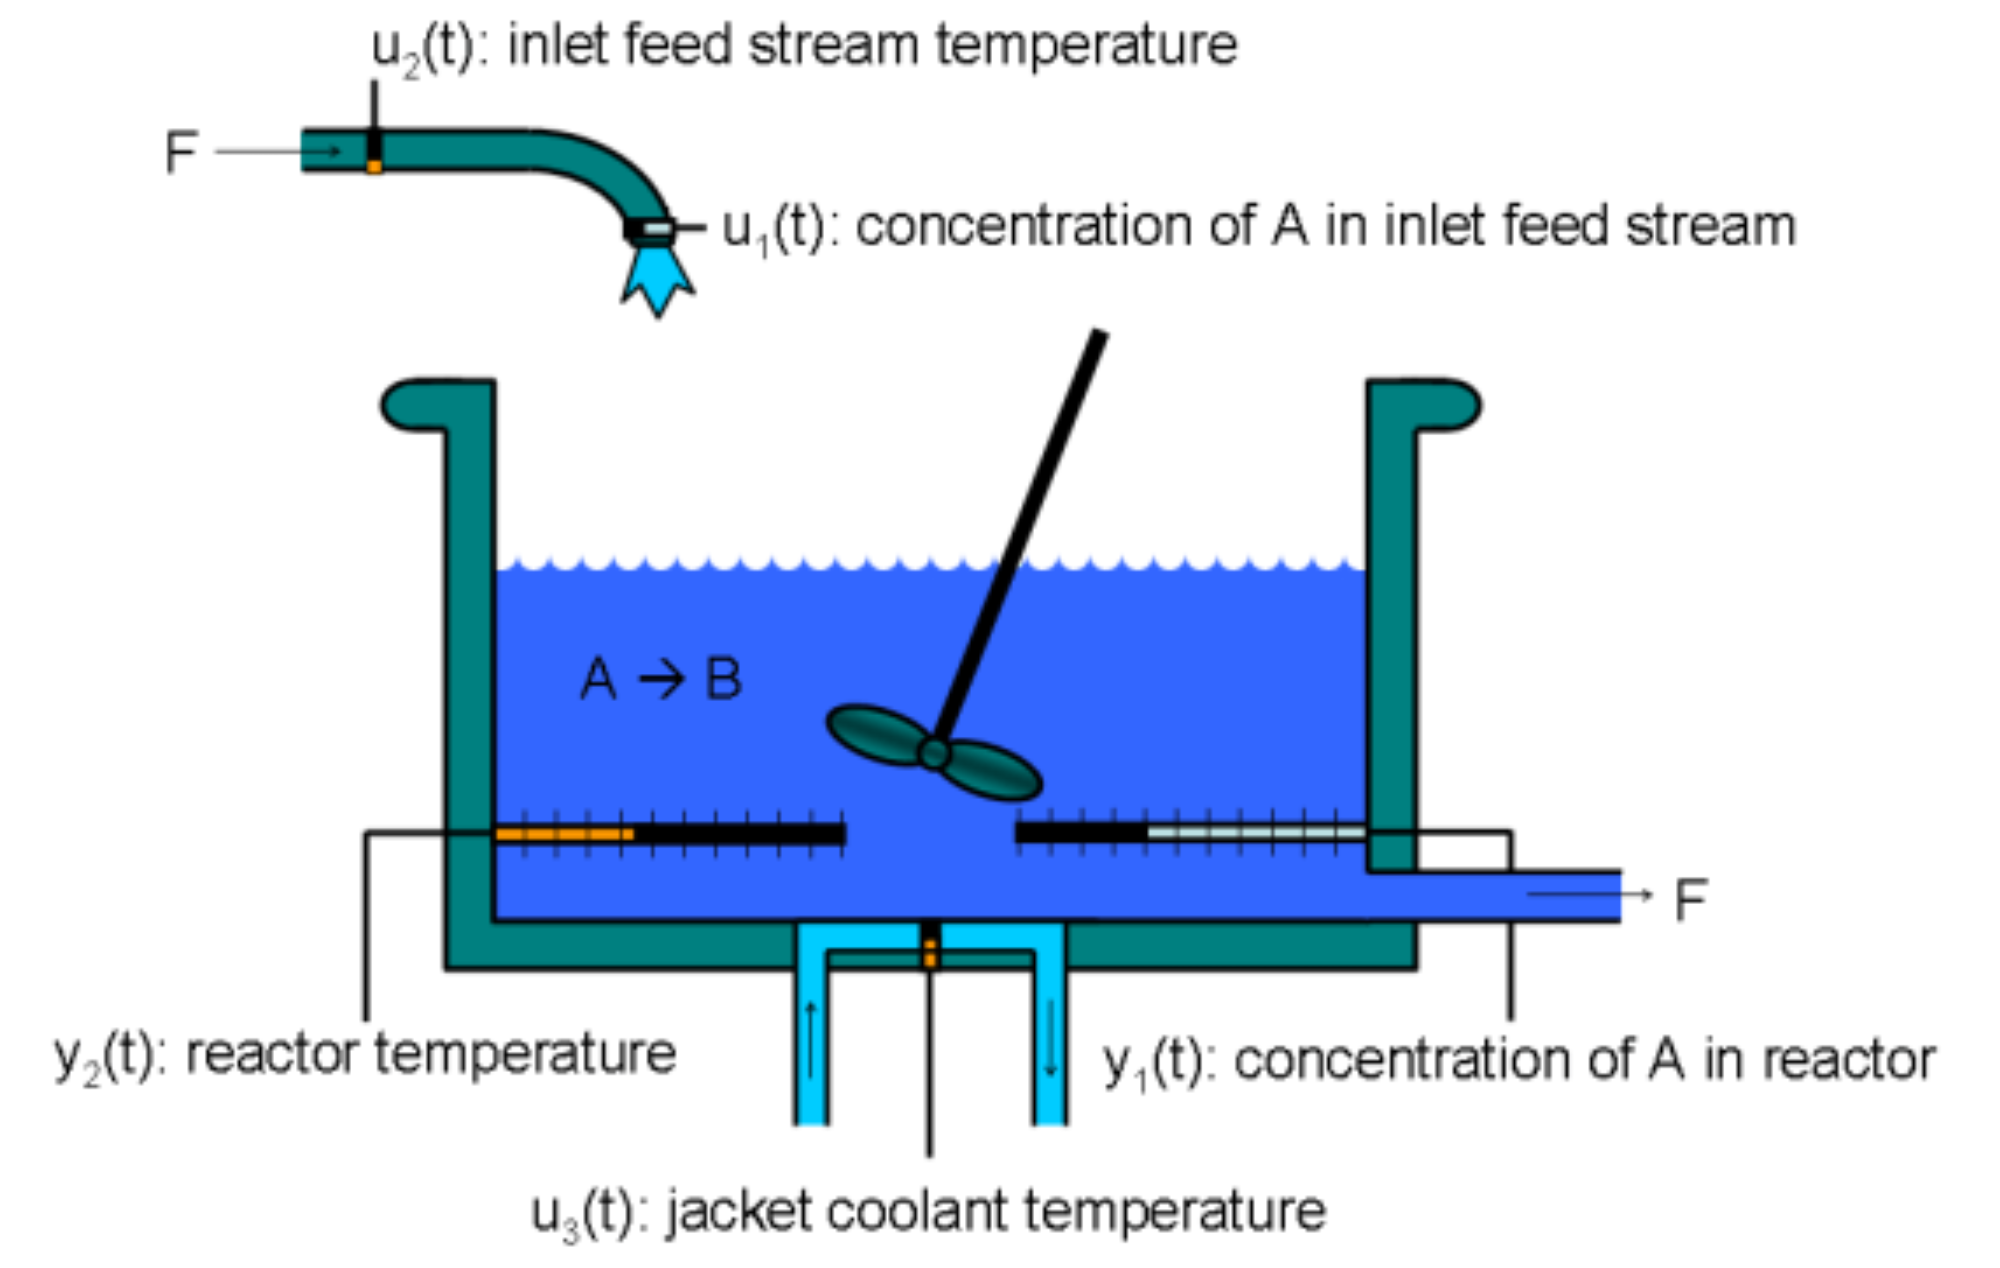

This example shows how to use Project Bonsai’s Machine Teaching strategies to learn a controller for a chemical reactor transitioning from low to high conversion rate. For background, see Seborg, D.E. et al., "Process Dynamics and Control", 2nd Ed., 2004, Wiley, pp. 34-36. This sample is largely adapted from the MathWorks’ [Gain scheduled control of a chemical reactor](https://www.mathworks.com/help/control/ug/gain-scheduled-control-of-a-chemical-reactor.html).

## Model Overview

The Continuous Stirred Tank Reactor (CSTR) is modeled as dynamic simulation derived from Reynold’s Transport Theoreom with unsteady energy balance. The following assumptions are required to get the equations into a form that can be written and solved using Simulink.

- The CSTR is perfectly mixed

- The mass densities, $\rho$, of the feed and product streams are equal and constant

- The liquid volume, $V$, in the reactor is kept constant constant by an overflow line

- The thermal capacities of the coolant and the cooling oil are negligible compared to the thermal capacitance of the liquid in the tank

- The heat of mixing is negligible compared to the heat of the reaction

- Shaft work and heat losses to the ambient can be neglected


$$\frac{dT_r}{dt}=\frac{F}{V}T_f+\frac{UA}{V\rho C_p}T_c-\left(\frac{F}{V}+\frac{UA}{V\rho C_p}\right)T_r-\left(\frac{\Delta H}{\rho C_p}k_0e^{-\frac{\Delta E}{RT_r}}\right)C_r \\
\frac{dC_r}{dt}=\frac{F}{V}C_f-\frac{F}{V}k_0e^{-\frac{\Delta E}{RT_r}}C_r$$


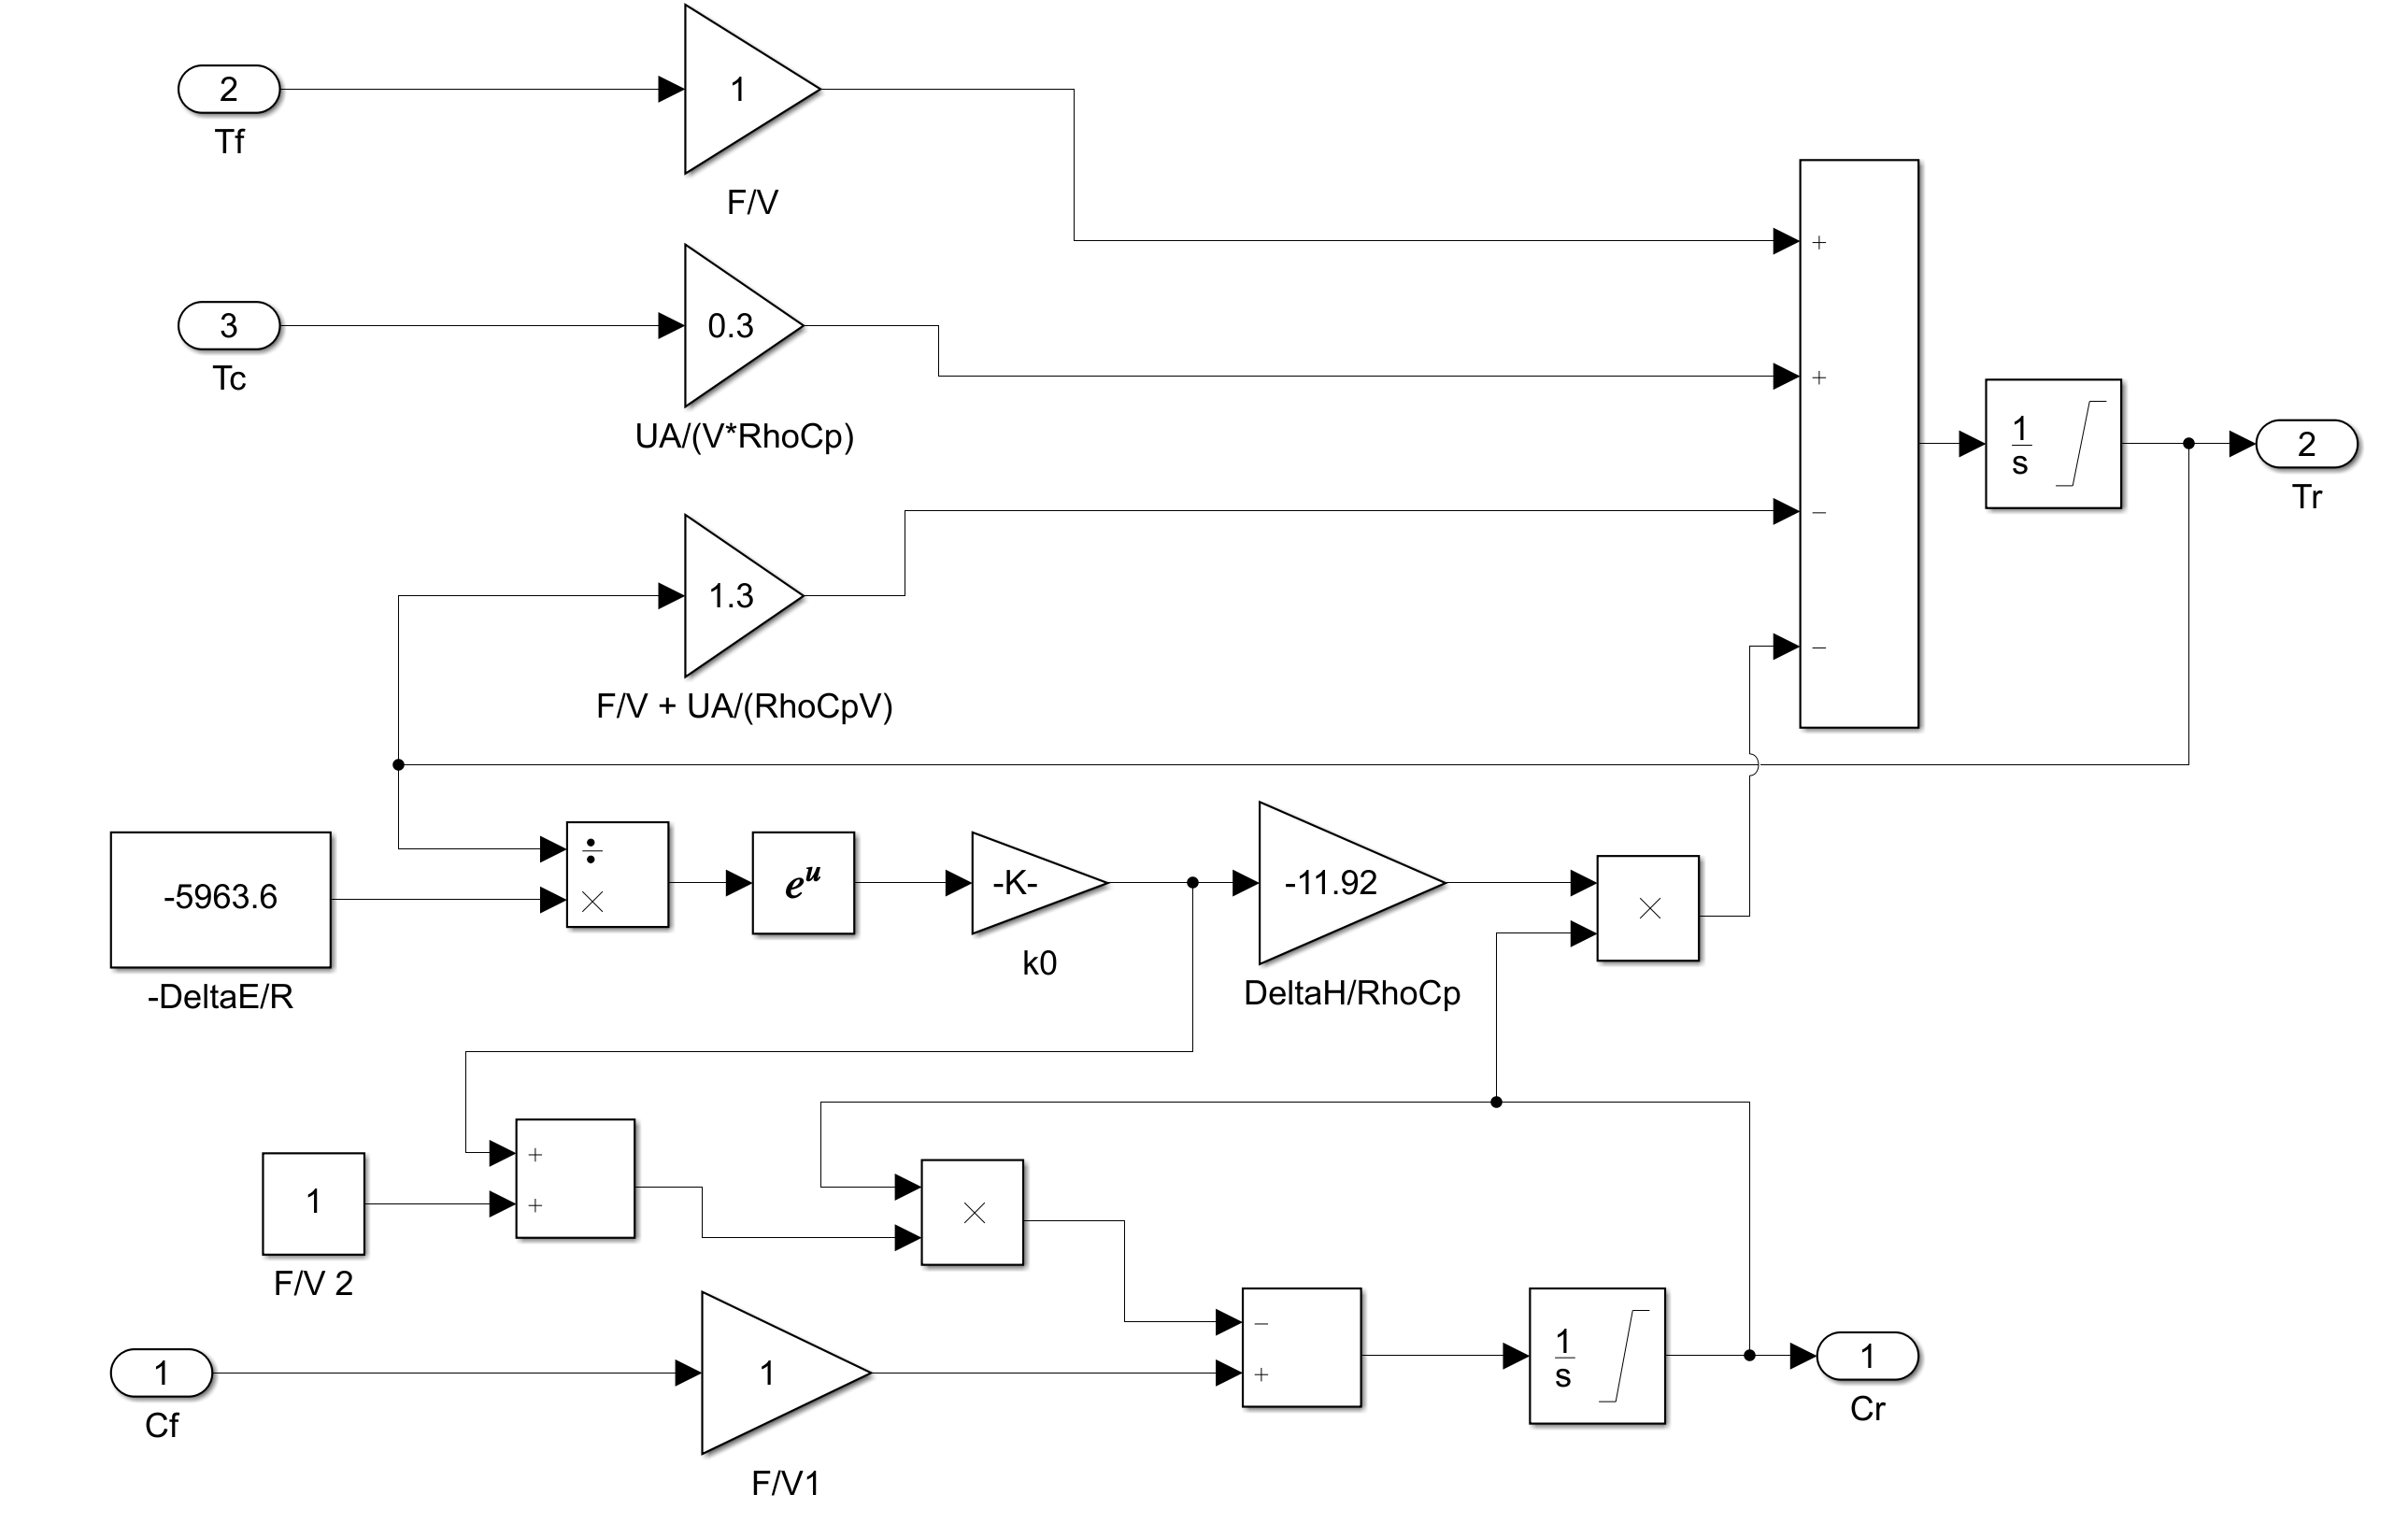

The dynamic model of the CSTR is nonlinear as a result of the many product terms and exponential temperature dependencies. Simulink is used to solve these equations with a fixed timestep, Ts,  of 0.5 minutes. The residual concentration, Cr, has units of $\frac{kmol}{m^{3}}$. The temperatures $T_f$, $T_c$, and $T_r$ are measured in Kelvin. 

The following products are required to run the model:

- Simulink Version 10.0 (R2019b) or greater

- Bonsai [Toolbox ](http://aka.ms/as/bonsai-toolbox)0.1.4

- Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup)

### Objective and Constraints

The chemical process requires transitioning a residual concentration of 8.57 $\frac{kmol}{m^{3}}$ initially down to 2 $\frac{kmol}{m^{3}}$. This irreversible chemical reaction is unstable in the mid range and must be properly cooled to avoid thermal runaway.  Thermal runaway is considered when the temperature of the reactor exceeds $400K$.


$$T_r < 400 K$$


 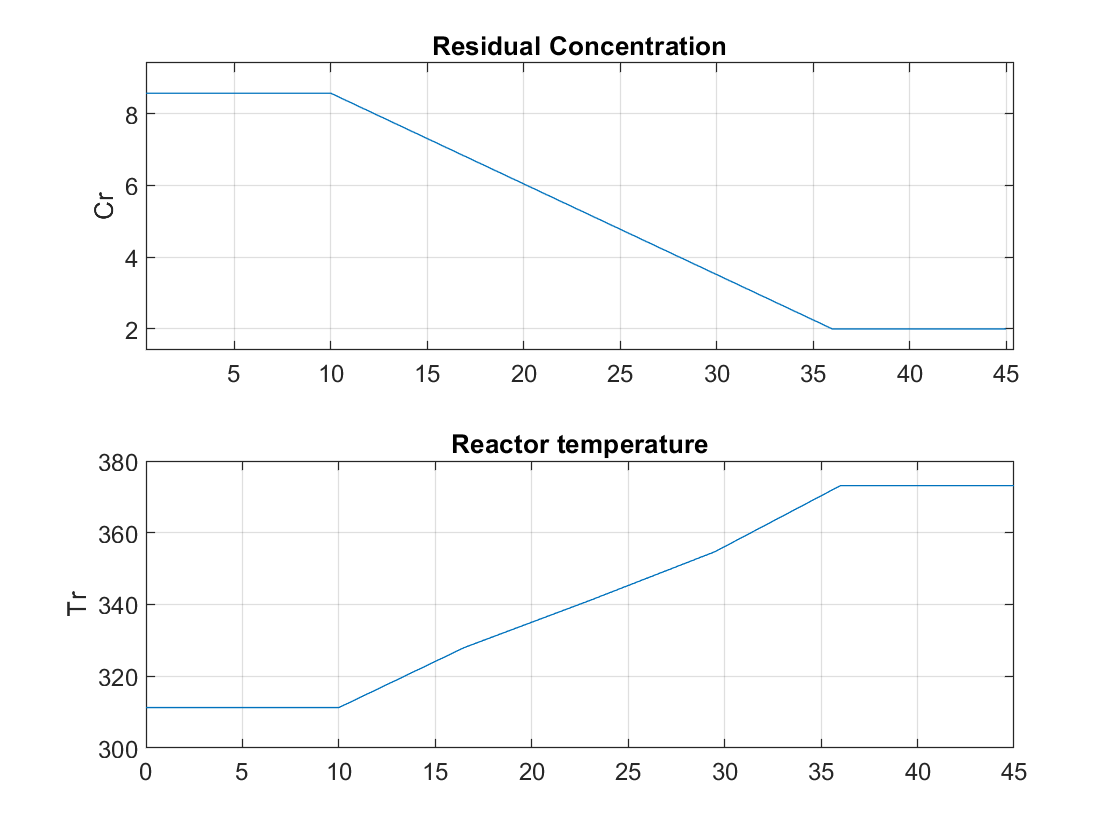

The target residual concentration and corresponding reactor temperatures at equilibrium are provided at each timestep for the ramp down. The transition lasts for 26 minutes long, however, the model is simulated for 45 minutes. 

The coolant temperature, $T_c$, is manipulated as input to the simulation to satisfy the objectives and constraints. The coolant temperature adjustment, $dT_c$, is relative to the initial equilibrium $TcEQ(1) = 297.88 K$.


$$T_c=TcEQ\left(1\right)+dT_c$$


The coolant temperature, $T_c$, is required to be rate limited to 10 degrees per minute (5 degrees per timestep). Inherently, the coolant temperature adjustment, $dT_c$, which is the variation from the initial equilibrium state, must be rate limited in the same manner. Thus, $dT_c$ can be larger than 10, as long as the increment from previous timestep doesn't exceed 5 degrees Kelvin.

### Metrics

In addition to the maxium reactor temperature, metrics like root mean squared (rms) error are useful in quantifying controller performance for a sequential decision making problem. This metric calculates the error from the reference at each timestep and basically aggregates the results throughout the chemical process.


$$C_r \ rms \ error: 0.5641 \frac{kmol}{m^{3}} \\
T_r \ rms \ error: 4.6046 K$$


### Experimental Setup

In this sample, we compare the performance of a benchmark Gain Scheduled Controller, to a Bonsai Brain, an Autonomous AI taught with the Microsoft Project Bonsai Platform.

## Benchmark Controller

To achieve these requirements, a PI controller is used in an outer loop and a lead compensator is used in the inner loop. Due to the slow sampling rate, the lead compensator is needed to adequately stabilize the chemical reaction at the mid-range concentration $C_r = 5.28 \frac{kmol}{m^{3}}$. This means that there are essentially two controllers being utilized, where the output of the cascaded controllers is ultimately $dT_c$. 

Typically, these controllers have fixed gains considering they are designed around equilibrium points. This problem has various equilibrium points as the residual concentration is transitioned from 8.57 to 2 $\frac{kmol}{m^{3}}$. When using constant gains for both controllers, it is apparent that the performance requirements are not met due to the challenging nonlinear dynamics. In fact, the chemical reactor was induced into thermal runaway because $T_r$ exceeds $400 K$. 

**PI Controller Results**

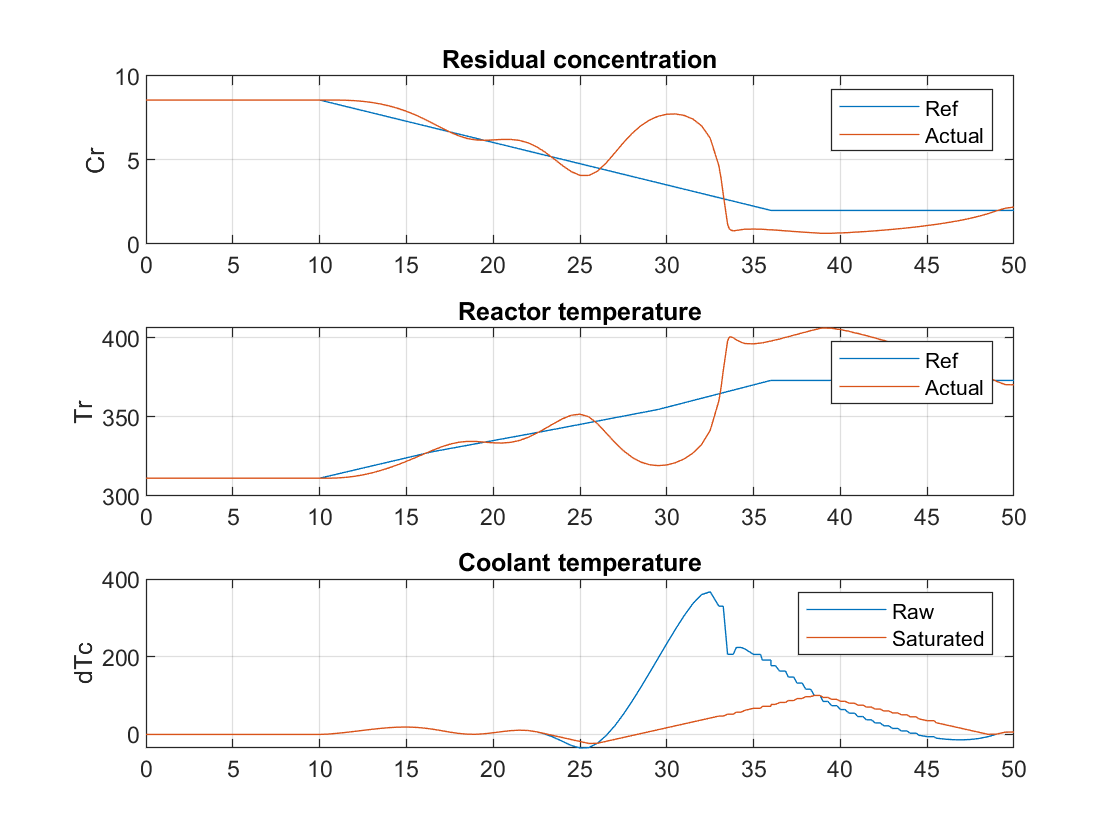

Because the reaction dynamics vary substantially with concentration, we further schedule the controller gains as a function of concentration. This is modeled in Simulink using Lookup Table blocks where this example simply provides the tuned gains for use. The design and tuning of these lookup tables involve using the Control System Design toolbox and more information can be found at [Gain scheduled control of a chemical reactor](https://www.mathworks.com/help/control/ug/gain-scheduled-control-of-a-chemical-reactor.html).

The benchmark controller successfully transitions the residual concentration from 8.57 to 2 $\frac{kmol}{m^{3}}$ without inducing thermal runaway. The tuning of the individual gains also ensured $T_c$ did not vary faster than 10 degrees per minute as shown by the raw and saturated $dT_c$ plots being overlayed on top of one another. 

**Gain Scheduled PI Controller Results**

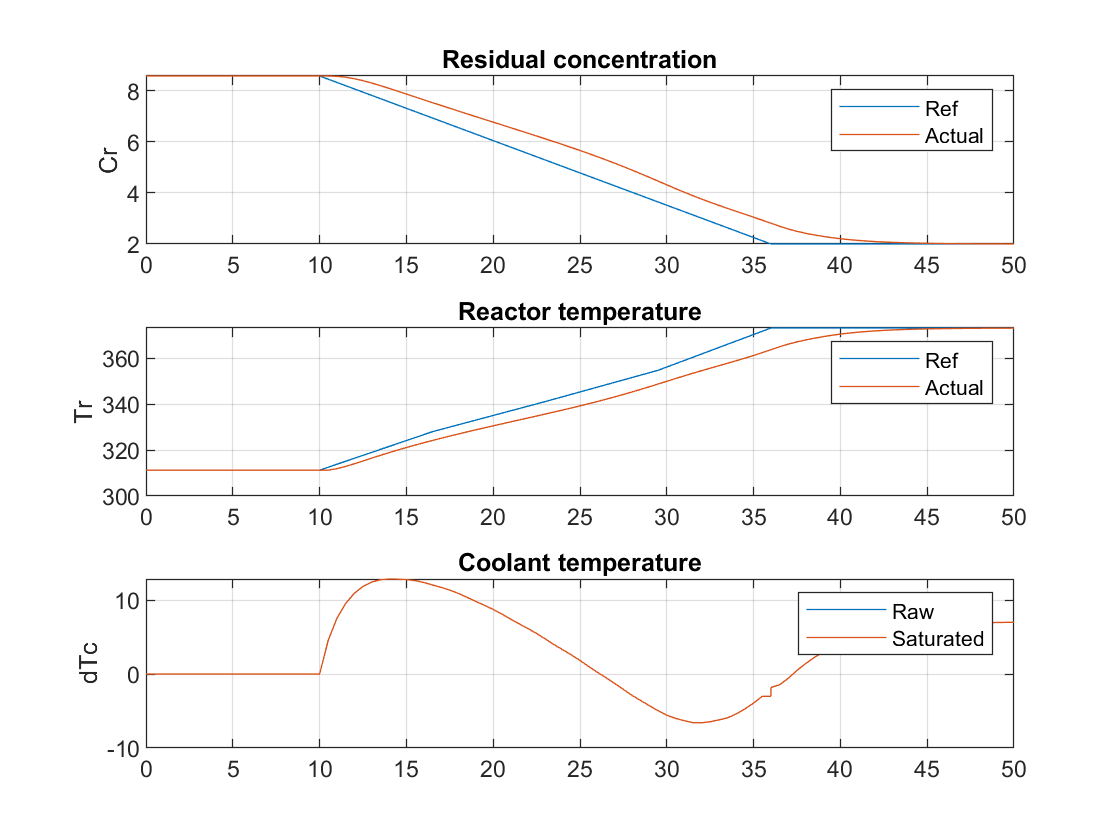

## Limitations of Benchmark Controller

The gain scheduled controllers were specifically designed for this transition of 8.57 to 2 $\frac{kmol}{m^{3}}$ for $C_r$. Choosing to specify a different starting and ending residual concentration would require calculating new initial equilibrium values for $T_r$, $C_r$, and $T_c$. Running the simulation with new target values without updating the initial conditions can lead to erroneous results. In order to re-design the gain scheduling for a new transition, we suggest obtaining the Control System Design toolbox and following the steps outlined in [Gain scheduled control of a chemical reactor](https://www.mathworks.com/help/control/ug/gain-scheduled-control-of-a-chemical-reactor.html). 

When dealing with real-world problems, noisy sensor measurements of your states (control variables) may make controller performance struggle in selecting the ideal action (manipulated variable). Having the sensor provide a slightly wrong value as input to the controller will result in degraded controller performance, especially when ran sequentially. We take the benchmark controller with gain scheduling and introduce 5% Gaussian noise to $C_r$ and $T_r$ in simulation. The root mean squared (rms) error of $C_r$ and $T_r$ are reported and are worse than the benchmark with no noise. The system ran into thermal runaway because $T_r$ exceeded $400K$.

**Gain Scheduled PI Controller with 5% noise Results**

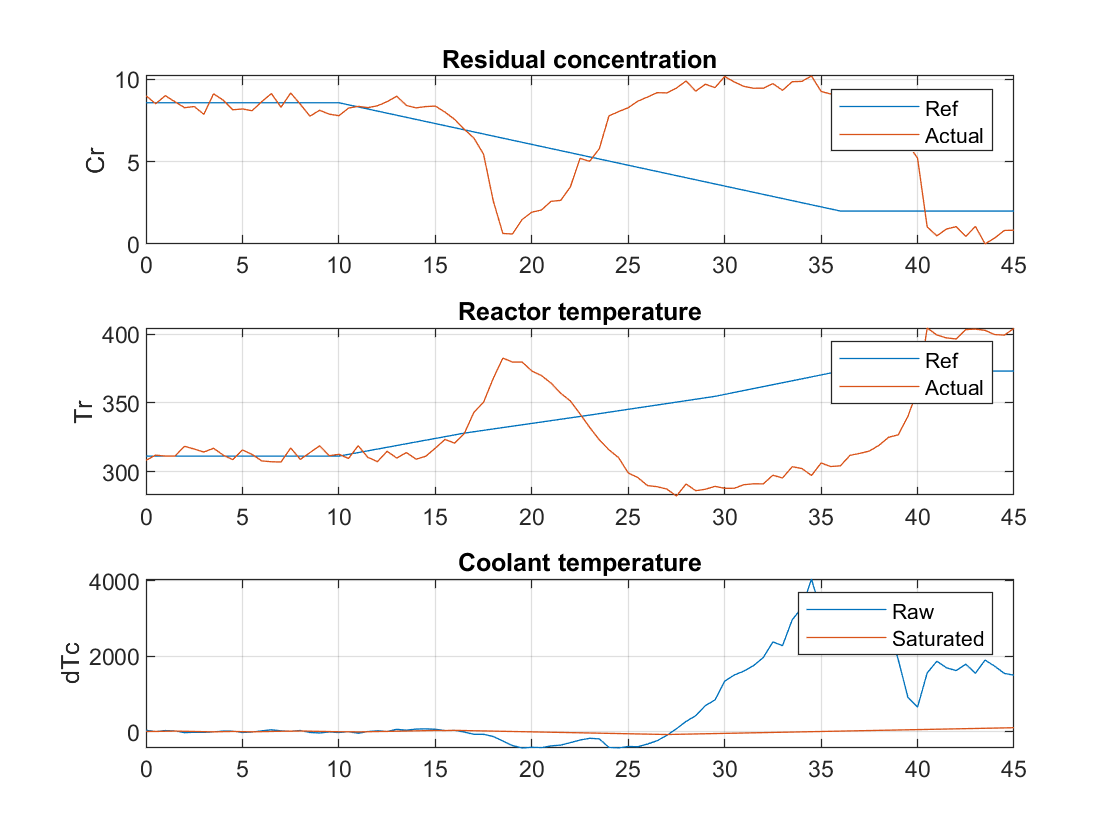 


$$C_r \ rms \ error: 3.8528 \frac{kmol}{m^{3}} \\
T_r \ rms \ error: 39.212 K$$


## Bonsai Brain

A Bonsai Brain is an Autonomous AI controller. Microsoft Project Bonsai is a low-code platform that allows non-data science, and non-AI experts, to use Machine Teaching to build AI controllers. 

Compared to PID control, AI can generalize across scenarios and handle uncertainty, like noise. Project Bonsai allows users to combine control and AI methods, specifically Reinforcement Learning (RL), to build autonomous systems. RL is not always a replacement of these technologies, rather it is a tool that can be used for targeted use cases and can enhance existing control methods. 

### Machine Teaching Benefits

Machine Teaching is the concept of injecting subject matter expertise into AI models. Project Bonsai’s Machine Teaching can learn a controller to transition the residual concentration without thermal runaway just like the benchmark. Using Project Bonsai, a controller is learned through trial and error in simulation. The learned controller is an approximation that may be beneficial when noise is present in sensor readings. 

### Brain Design

For this demo brain was design with mulitiple concepts that represent different operating conditions:

- The "steady state" concept controls the brain when the system is trying to produce the steady state residual concentration 8.57 $\frac{kmol}{m^{3}}$. 

- The "modify concentration" concept controls the brain when the sytem is trying to transition from producing 8.57 to 2 $\frac{kmol}{m^{3}}$ over a period of 26 minutes.

- The "select" concept chooses either the "steady state" or "modify concentation" concept depending on the reactor conditions.

**Brain Design Diagram**

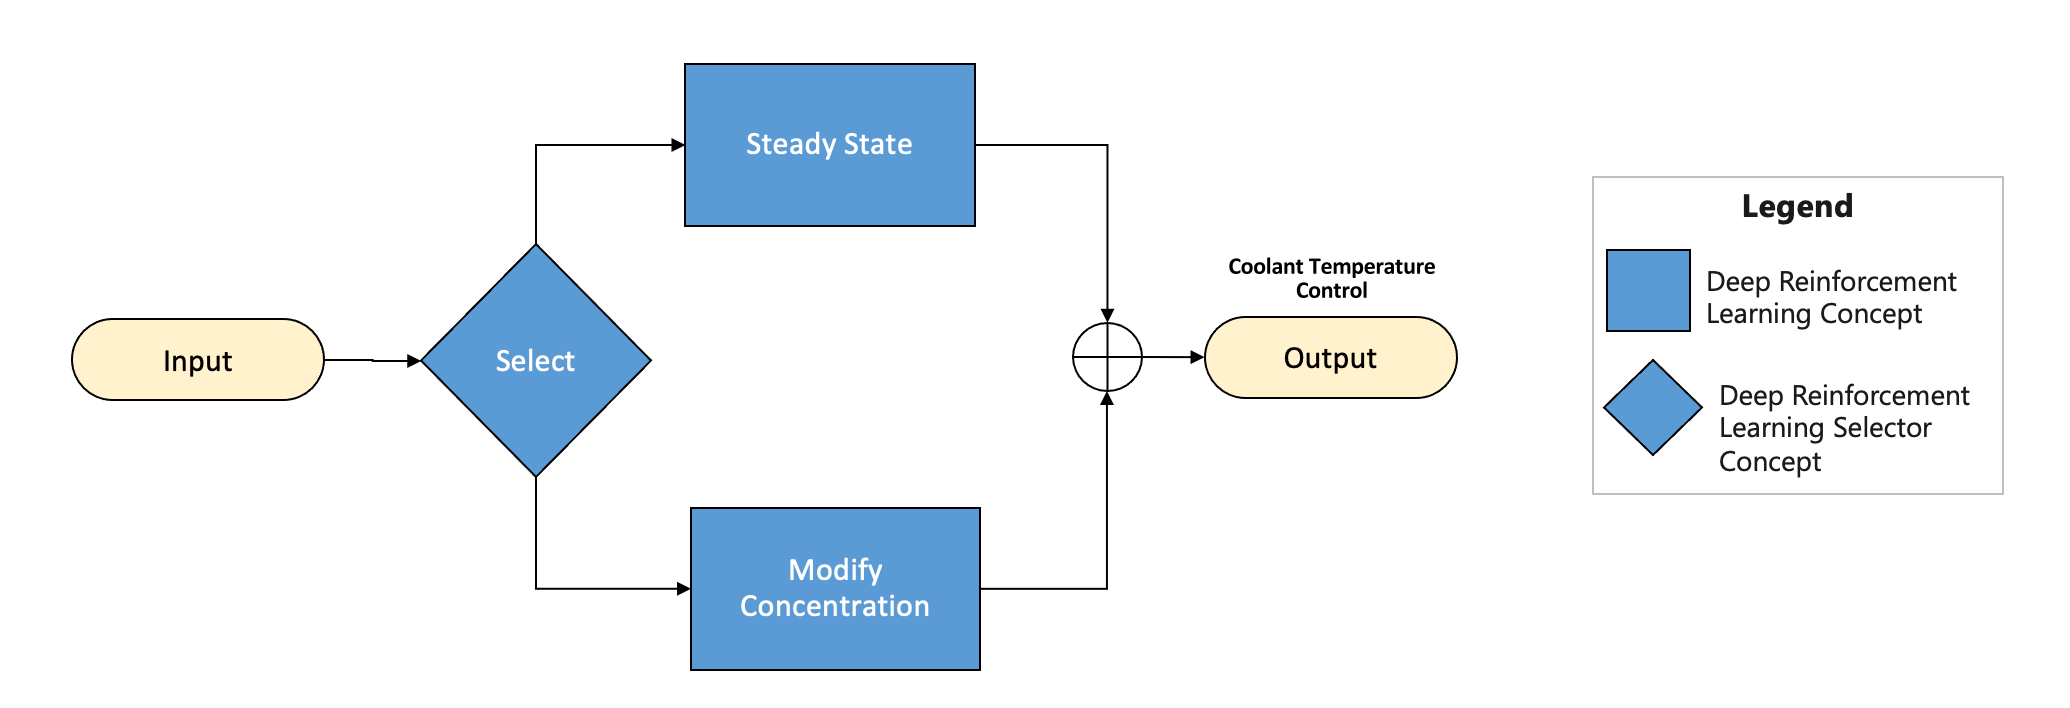

## **Run Benchmark Gain Scheduled Controller**

To run the baseline controller (gain scheduled PI), first open the Simulink model:

CSTR_PI;

Now run the script:

Constant Gains: Target Concentration followed with RMS of: 1.4835
Constant Gains: Target Reactor Temperature followed with RMS of: 18.1427


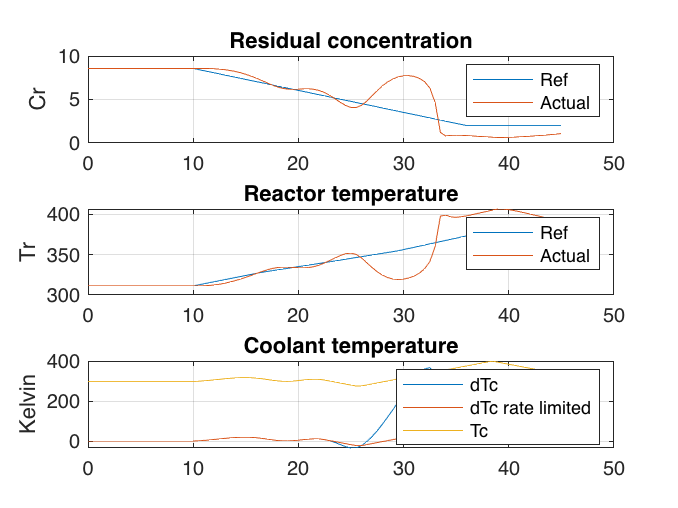

Benchmark: Target Concentration followed with RMS of: 0.56409
Benchmark: Target Reactor Temperature followed with RMS of: 4.6046


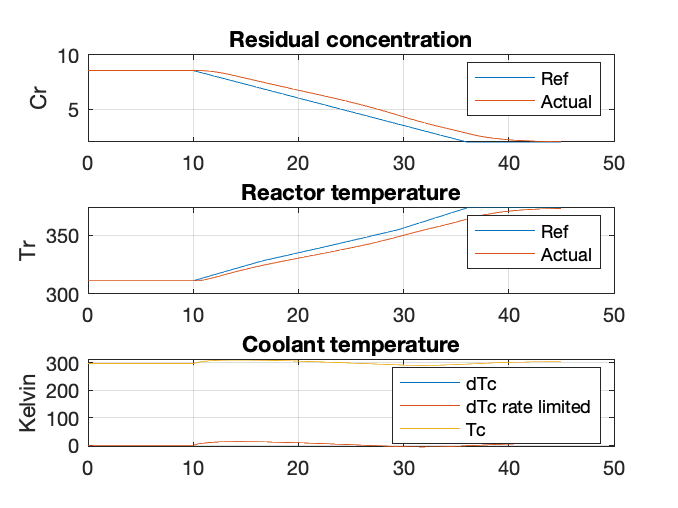

Stretch Benchmark (5% noise): Target Concentration followed with RMS of: 1.5477
Stretch Benchmark (5% noise): Target Reactor Temperature followed with RMS of: 14.1124


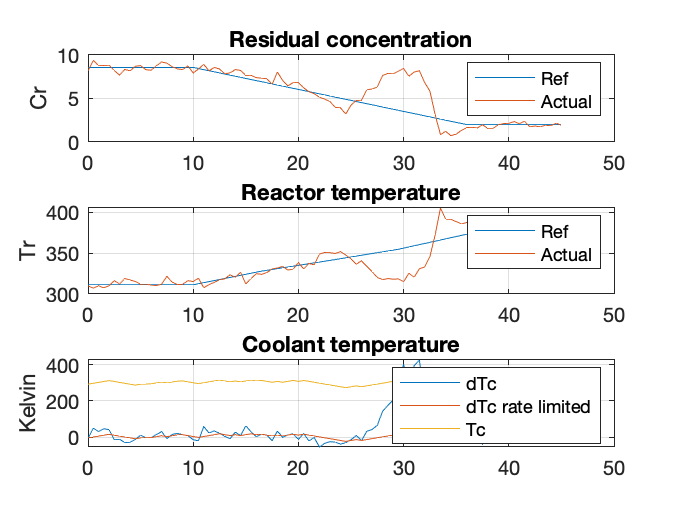

run_PI;

After entering this command, benchmark will be run under 3 scenarios (see more bellow). Graphs will be shown for each of them independently.

### Benchmark - 3 Scenarios

These are the three scenarios that are run for using conventional controllers:

- Constant Gains: This scenario runs without scheduled gains for the 2 bechmark controls. It allows the user to assess the simulation non-linearities that force benchmark to require 2 controls, with 5 non-linear gains.

- Gain Scheduling: This second scenario runs benchmark as engineered. It allows you to assess how well does the current system perform. New controllers (including Bonsai brains) will be compared against this scenario to assess over/under performance.

- Benchmark with Noise:This last scenario assesses how well does benchmark perform under the influence of gaussian noise on the temperature/concentration read-outs. In a real application, read-outs might be subject to noise, as well as measurement error. This scenario tests robustness to noise.

### Modifying Parameters

Each scenario is introduced in a separate section inside the `run_benchmark.m` script. There's 2 elements that you might be the most interested in changing:

(1) Noise Magnitude: This is the amount of noise introduced to the states (controlled variables) in the model. 

To modify the noise introduced during Benchmark Stretched, go and find the following line under "Benchmark (stretch - 5% noise)" section:

% Percentage of noise to include
noise = 5;

Modify 5 to whichever value you desired within [0, 100] range.

(2) Signal Reference: This is the reference trajectory of Cref. There are 5 signals preconfigured in the signal builder. The default is signal 2.

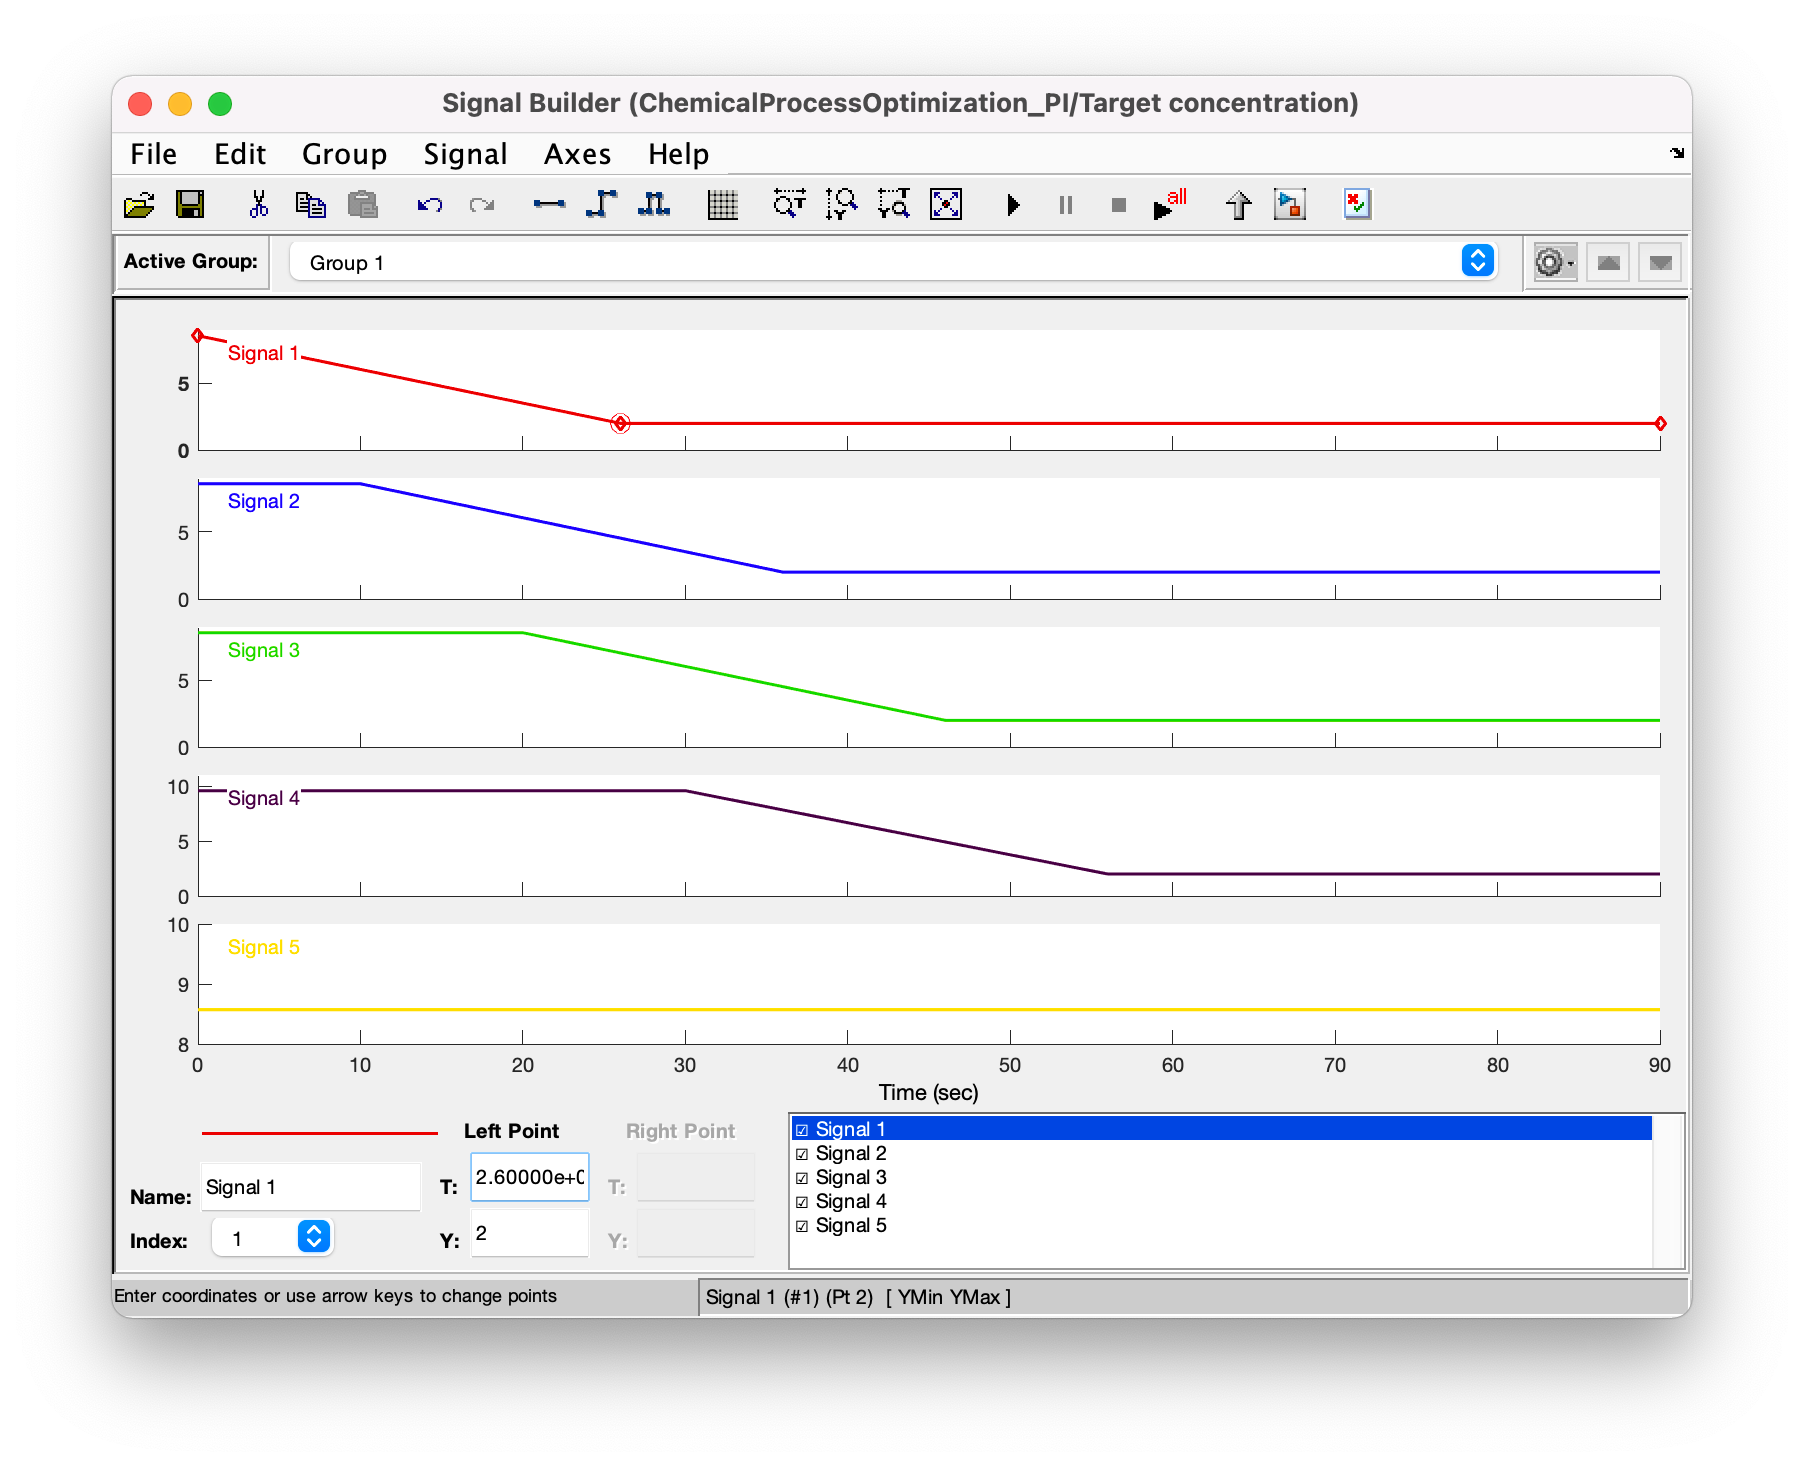

### Important!

To make sure that you don't run into issues when training with Bonsai, do not make changes to signals 1 - 5 of the signal builder. If you would like to experiment with different reference tajectories, create additional signals.

To modify the signal reference simulated, change the following line under "Initialization Workspace" section:

% Set Refrence Signal
Cref_signal = 2;

## **Train Bonsai Controller locally**

After getting acclimated with the Chemical Process Optimization model and setting up a Bonsai account, you are now ready to train your first Bonsai brain for this simulation. 

To train the Bonsai brain, first open the Simulink model:

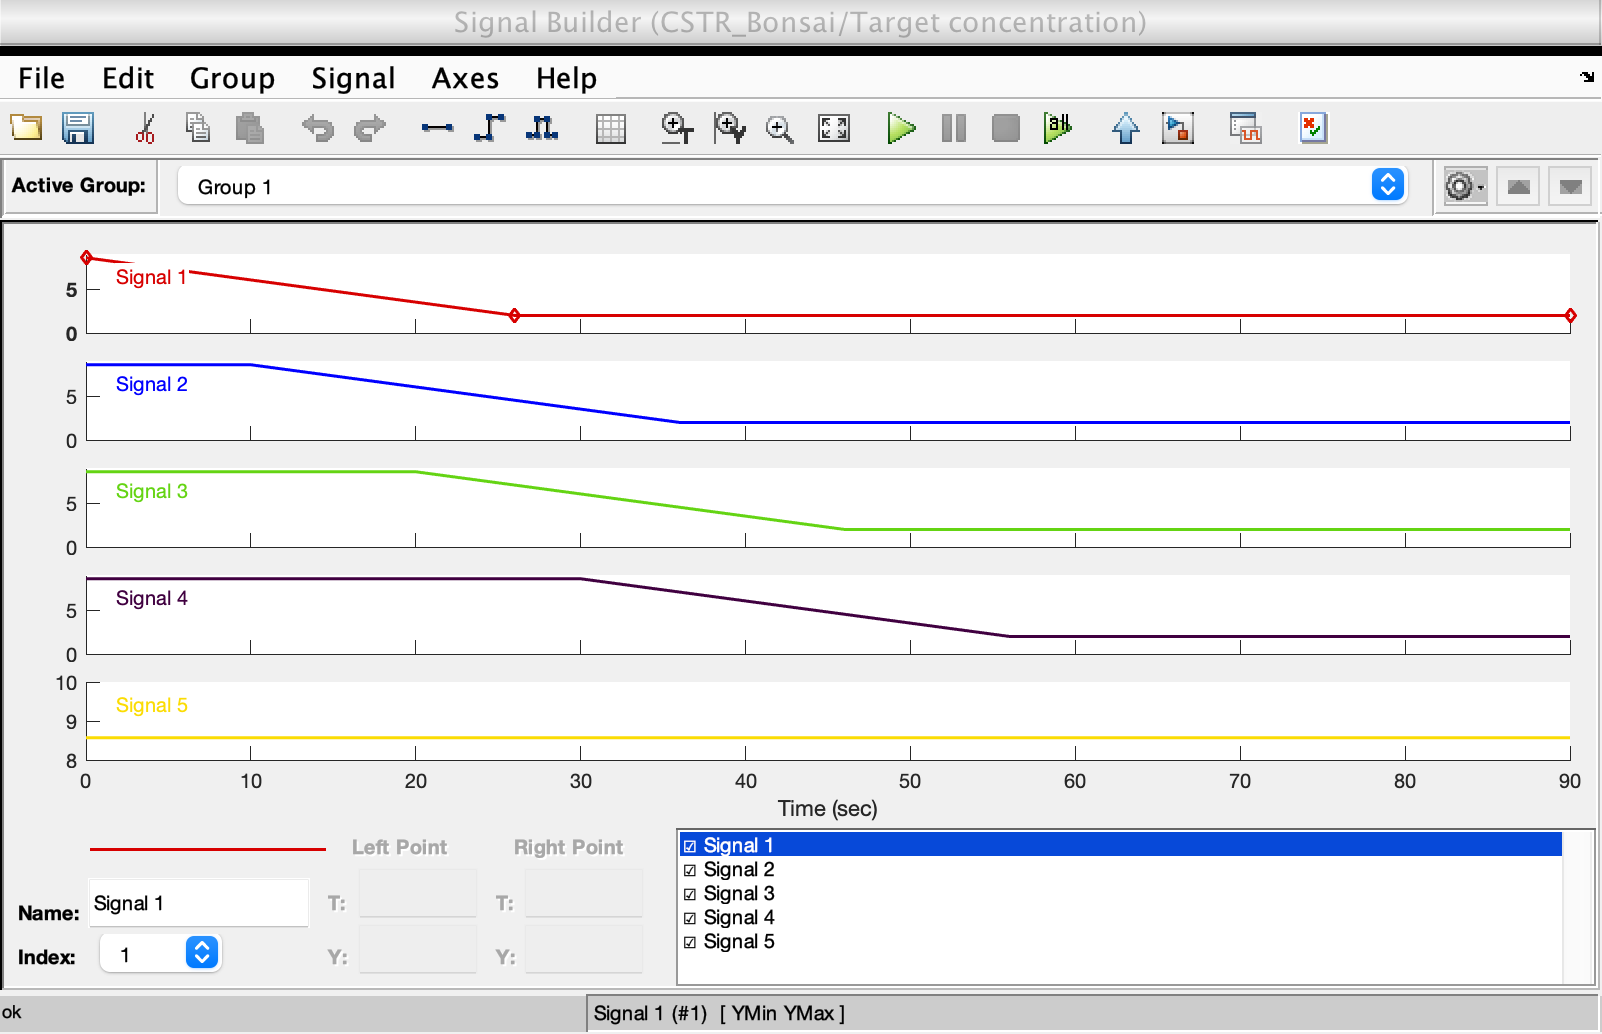

CSTR_Bonsai;

In this model, the PI controller has been replaced with the Bonsai block.

### Connect to Bonsai

Follow these steps to connect this model to Bonsai for the first time. 

(1) If you have not done so, you will need to create a Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup). 

(2) From the Bonsai UI, you will need to capture your Bonsai **Workspace ID **and **Access Key. **You can find this information by clicking on your username in the top right and selecing **Workspace Info**.

(3) Save your workspace info in a hidden .env file. To do this, open **keys.env**, and enter your **Workspace ID** and **Access Key**, and save as** .env.**

(4) Create a brain. In the Bonsai UI click `+Create Brain:`

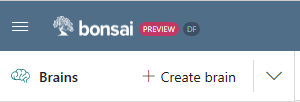

This will prompt for the type of brain to create:

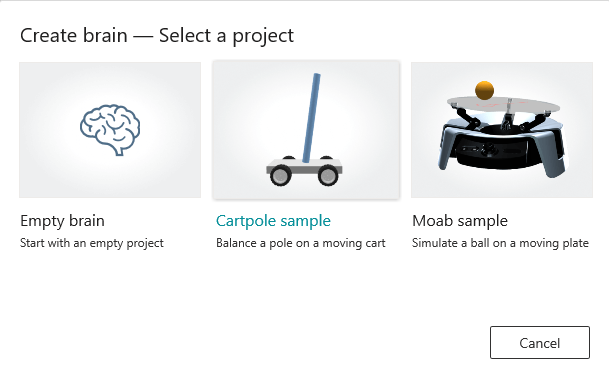

Select `Empty brain `and enter a name in the prompt. In this example, the brain is called `cpo-demo-brain``. `Click the `Create brain` button`.`

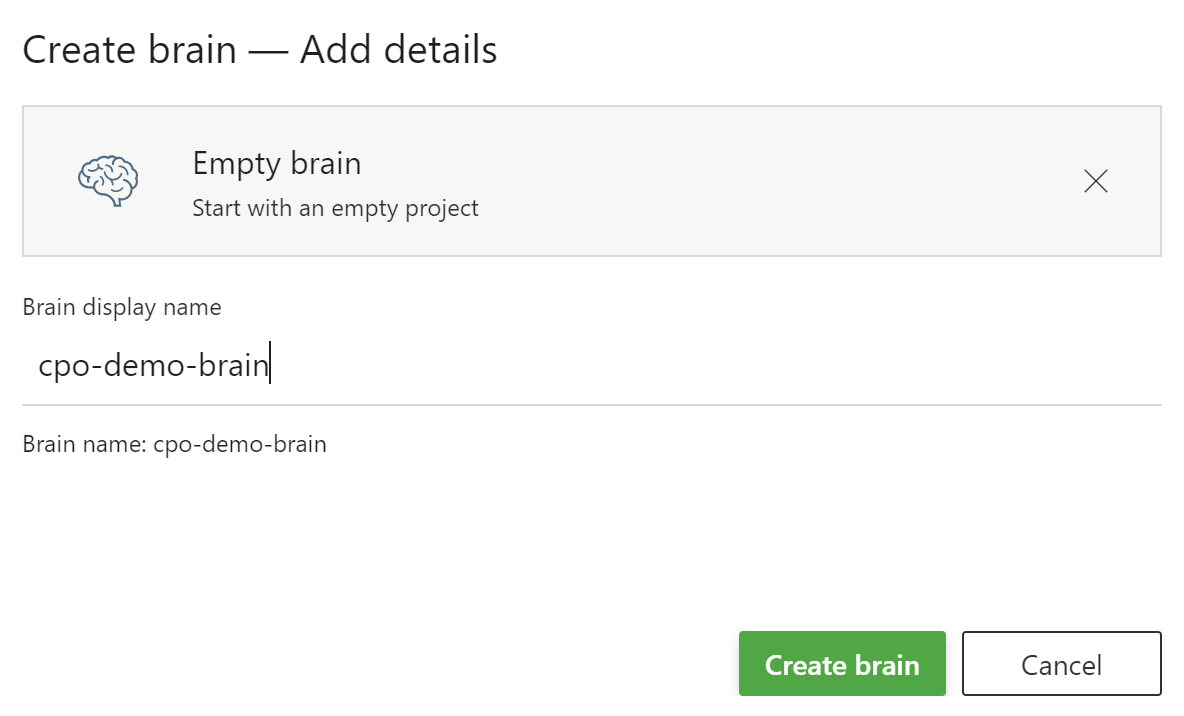

This will create your brain and take you to the **Teach** tab:

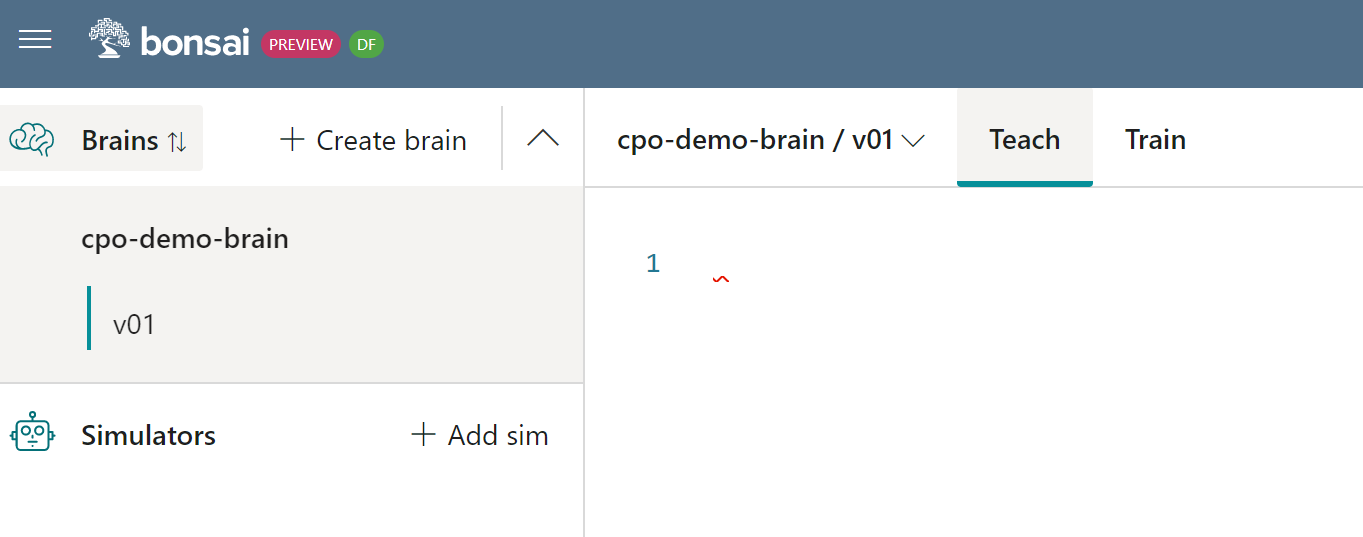

Note, the INK file will be empty. Now, open the `brain.ink` file. Copy the full content ("CTRL+a", then "CTRL+c") and paste it on the website.

You are now ready to train locally with the Bonsai Controller.

### The `bonsaiConfig `File

The `bonsaiConfig` function is used to setup the connection between your model and the Bonsai platform. Here you describe several key factors:

- **name** - The name of your simulator (you will see this when you connect to Bonsai)

- **url** - Optional. The URL used to connect the Bonsai API service

- **timeout** -- Optional. The value in seconds for a timeout. A default value of 60 seconds is used if this is not explicitly set. **If you receive timeouts when running bonsaiTrain, increase this value up to 300**.

- **workspace** - The workspace value obtained from the Bonsai platform. We recommend storing this value in a .env file.

- **accessKey** - the access key obtained from the Bonsai platform. We recommend storing this value in a .env file.

- **outputCSV** - Optional. When running locally, this can be helpful for debugging your model and the Bonsai connection.

- **stateSchema** - *Important. *This is the *order* of the values as they appear in the input parameter of the Bonsai block. Even if you use a Bus as your input the Bonsai block must understand the order of the values. These names must match what is in your inkling code in Bonsai. 

- **actionSchema** - The actions the brain will perform. Input ports to the Moab subsystem. The names must match what is in your inkling code from Bonsai. Order is important. 

- **configSchema** - The values that the Bonsai brain will send during a training episode. These are used as configuration parameters to initialize the model with different states, such as ball size, position, or velocity. 

We recommend creating a .env file for setting up environment variable for `SIM_WORKSPACE `and  `SIM_ACESS_KEY `to prevent accidentally saving credentials into code revisions. Another option is to save your Workspace ID and Access Key direclty in bonsaiConfg.m.

### Run Bonsai Training with a Single\ Local Instance 

Now that the connection to Bonsai has been configured, run the `bonsaiTrain` function. Once you see the Sim successfully registered message below or in the MATLAB Command Window, switch over to the [Bonsai UI](http://preview.bons.ai), and click the `Train` button`.`

bonsaiTrain; 

[2022-03-04:11:02:48UTC Session]
Bonsai MATLAB Toolbox Version:0.1.6
[2022-03-04:11:02:48UTC BonsaiConfiguration] BonsaiConfiguration is valid.
[2022-03-04:11:02:49UTC Session] Sim successfully registered

[2022-03-04:11:02:49UTC Session] Requesting events until EpisodeStart received...
[2022-03-04:11:02:59UTC Session] Received event: Idle, please visit https://preview.bons.ai and select or create a brain to begin training. Hit "Train" and select simulator "Simulink - Chemical Process" to connect this model.
[2022-03-04:11:03:10UTC Session] Received event: Idle, please visit https://preview.bons.ai and select or create a brain to begin training. Hit "Train" and select simulator "Simulink - Chemical Process" to connect this model.
[2022-03-04:11:03:20UTC Session] Received event: Idle, please visit https://preview.bons.ai and select or create a brain to begin training. Hit "Train" and select simulator "Simulink - Chemical Process" to connect this model.
[2022-03-04:11:03:30UTC Session] R

[2022-03-04:11:05:45UTC Session] Unregistering SessionID: 460341508_10.244.27.112
[2022-03-04:11:05:45UTC BonsaiRunTraining] Session terminated by user.


After clicking `Train``, s`elect the Unmanaged simulator `Simulink - Chemical Process` simulator (this assumes you left the .name value the same in bonsaiConfig). 

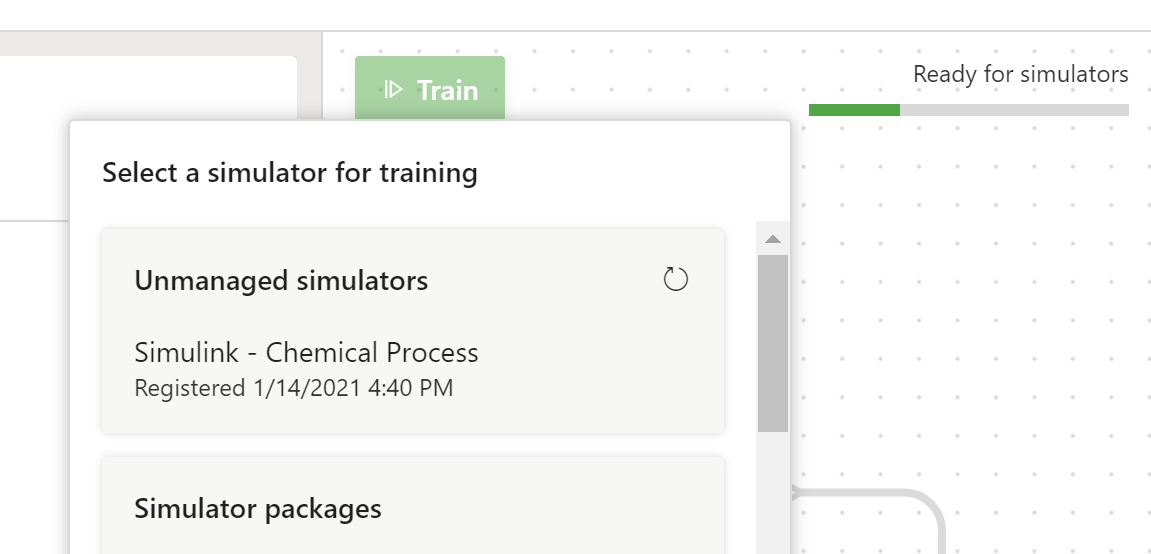

After a short time (typically <2 minutes) the sim will connect.At this point the model is launched and parameters are set, so you may see a delay while this occurs and Mechanics Explorer launches.

After this process completes you will see the iterations per second displayed: 

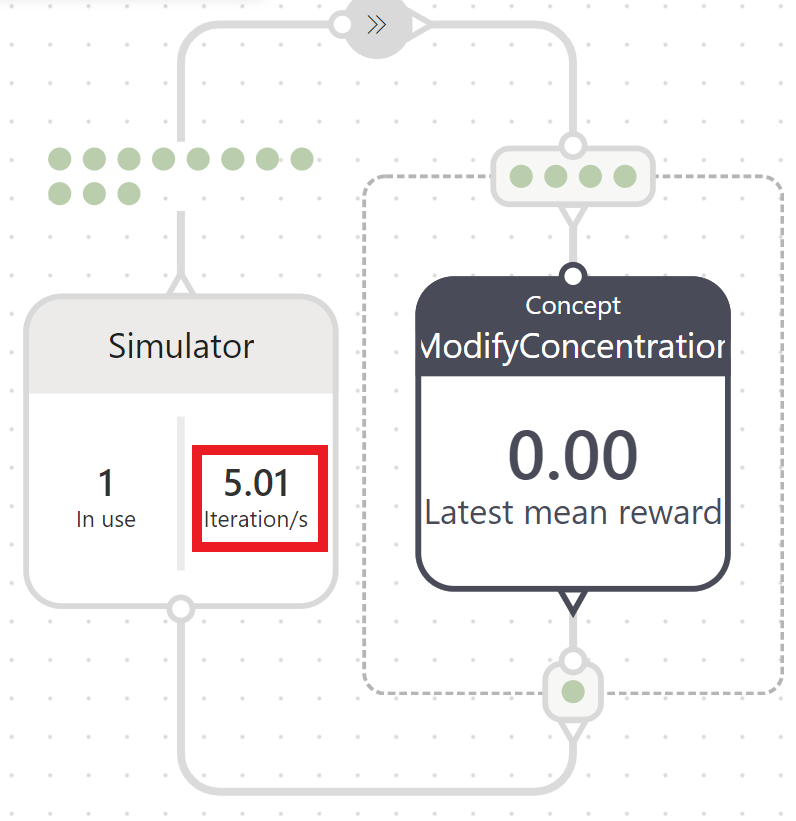

Check the MATLAB Command Window to see a series of outputs indicating communication with the Bonsai brain.

Connection speeds vary, but this model mostly operates at about 3-7 iterations per second. 

To stop training, click `Stop Training `in the Bonsai UI.

**Note:** To terminate the simulation in MATLAB, use Ctrl+C in the Command Window. Be sure to disable Fast Restart from the Simulation tab in the Simulink model.

## Scale Bonsai training on the Cloud

Scaling the model greatly improves training times. Once you have verified your model connects and runs locally, you can zip, upload, and scale your model on the cloud. Close Simulink and zip the entire contents of the folder that contains the model. 

For example, if your folder structure is:

`chemical-process-optimization `

`└─── img`

`|    └── ... image files ... `

`|─── bonsaiAssess.m`

`|─── bonsaiConfig.m`

`|─── bonsaiTrain.m`

`|─── Chemical_Process_Optimization.mlx`

`|─── ChemicalProcessOptimization.slx`

`|─── cpo_tutorial_1.ink`

`|─── cpo_tutorial_2.ink`

`|─── CSTRData.mat`

`|─── init_vars.m`

`|─── LICENSE`

`|─── README.md`

`└─── run_benchmark.m`

Then you only need to zip the parent **chemical-process-optimization** folder. It is suggested you remove your` slprj` folder and` .slxc `files before zipping up the folder contents. You also do not need any` .csv `files, neither the `img/` folder`. `Call the file `chemical-process-optimization.zip. `

### Upload the Model

Back in the Bonsai UI, next to `Simulators``,` click the `Add sim` button.

This will open a dialog. Select `MathWorks``. `Then you can upload your zip file`:`

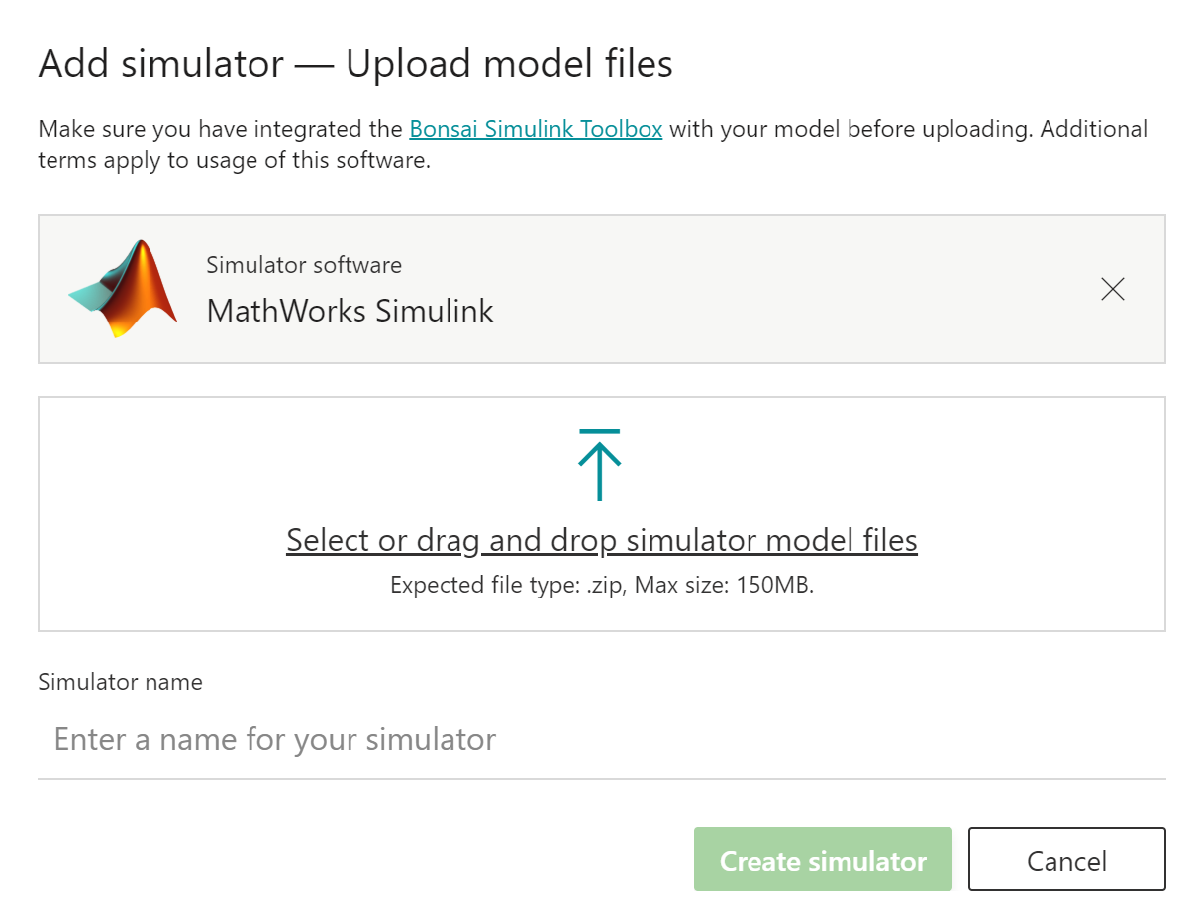

Select or drag the `chemical-process-optimization.zip `file created previously`. `

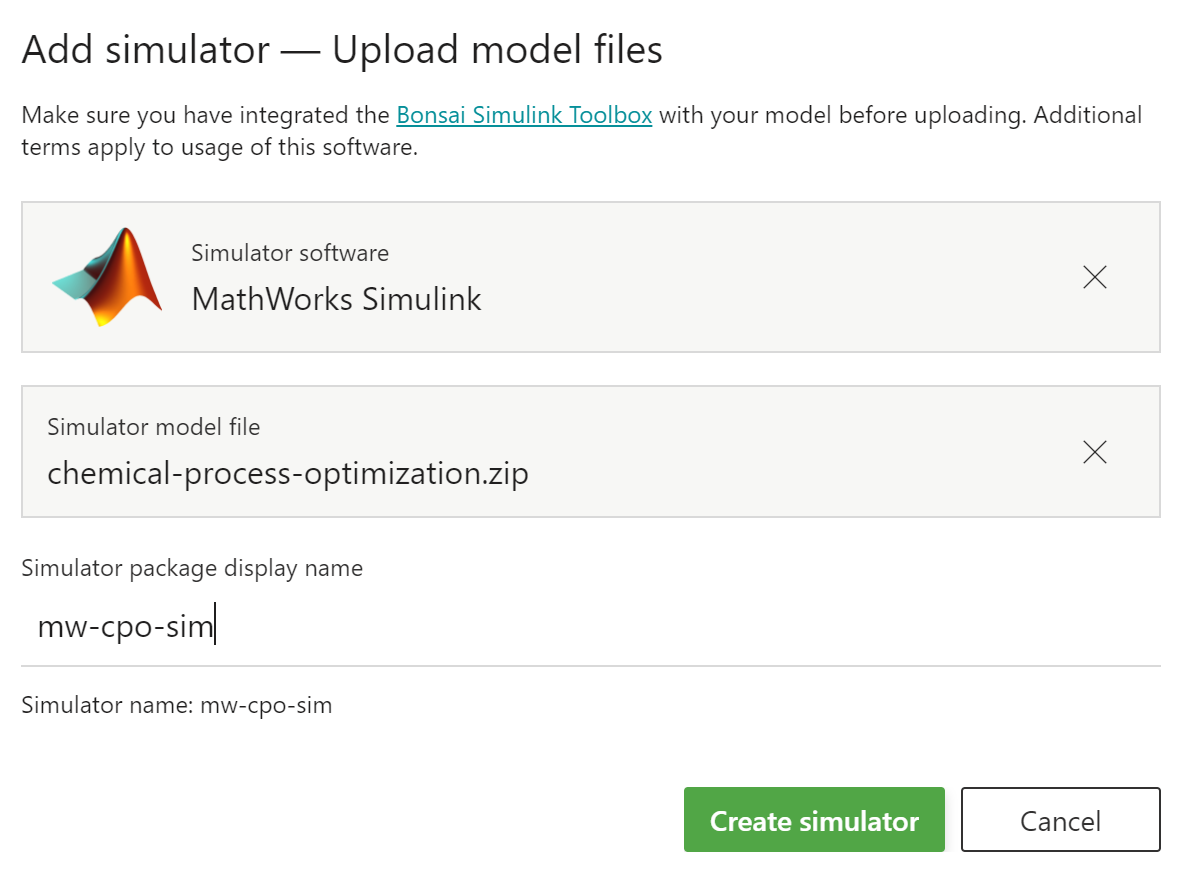

Give your simulator a name, then click `Create simulator``. `

**Note: ***It may take up to 20 minutes to create the simulator image. *You will see the ACR path displayed after successful creation.

After the simulator is created you will see the new simulator appear under the `Simulators`` section.`

**Note: **Be sure your brain is not training prior to changing the package statement.

## Update Inkling with Simulator Package

Click the `Teach` tab. 

In inkling, for each of the three concepts, update the simulator definition with the name of the simulator you gave during the Add Simulator dialog above. Add the line,` package "mw-xpo-sim", `as shown below for each concept.

## Train the Brain

The three concepts need to be trained separately. First, select the **SteadyState** concept and click the `Train` button. This will create several instances (from 1-50) using your uploaded model to train your brain. If you did not include the name of hte simulator package in the inkling, you will be prompted to select the simulator package from the drop down window. 

Each concept will need to be trained 

**Note: **It may take up to 10 minutes for your simulators to connect.

## Assessing Brain Performance 

You can assess the trained brains in 2 ways:

(1) Assess Brain in Bonsi: This allows you to test the trained brain in Matlab while still hosting the brain in the Bonsai Platform.

(2) Assess Exported Brain: This allows you to export and test the trained brain locally in Matlab.

### Assess Brain in Bonai 

Assessment allows you to test the performance of a trained brain while still hosting that brain in the Bonsai platform. 

After training your brain(s) you will want to assess their performance. Run:

bonsaiAssess;

This will begin assessment and connect to the Bonsai platform, similar to training. If your model is not open this will also open the model.

Click the `Run` button in Simulink.

In the Bonsai UI, click the `Start Assessment `button.

If the package statement is still in Inkling, it will use a managed simulation for Assessment. If you wish to run an unmanaged simulator from your personal computer, uncomment the package statement. Then click the `Simulink - Chemical Process` simulator. 

Your local model will iterate using the brain in assessment mode.

If you receive the message `Last event was Unregister, done requesting events `then you may need to increase the timeout value in bonsaiConfig.

### Assess Brain in Matlab and compare to benchmark

- From you computer, login to docker (docker login) with credentials and make sure docker is running on your local system.

- Export your brain from the Bonsai platfrom.

- Pull the brain onto your local system using the "docker pull" command generated in the Deployment Instructions.

- Start the brain using the"docker run" commands generated in the Deployment Instructions.

- Configure the endpoint in bonsaiConfig.m or as an environment variable. (defaults to localhost:5000)

- Run bonsaiExportConnect:

bonsaiExportConnect;

    7. Run the following script to test the Brain against the Benchmark Gain Scheduled PI Controller.

        This script will run 4 simulation scenarios and plot the results for comparison:

- 1st: Gain scheduled PI without noise

- 2nd: Gain scheduled PI with noise (as configured below)

- 3rd: Brain with no noise

- 4th: Brain with noise (as configured below)

run_BrainVsBench;